%% =============================================================
%  1) IMPORTAR DATOS DESDE EXCEL
% ==============================================================
file = "Primera entrega- Grafica Fuerza vs Voltaje  .xlsx";

% ---------- CARACTERIZACIÓN ----------
opts = spreadsheetImportOptions("NumVariables",5);
opts.VariableNames = ["Velocidad","PWM","Angulo","AnguloRelativo","AnguloRelativoRad"];
opts.VariableTypes  = ["double","double","double","double","double"];
opts.Sheet = "caracterizacion";
opts.DataRange = "A2:E300";
Caracterizacion = readtable(file, opts);
Caracterizacion = rmmissing(Caracterizacion);

% ---------- IMPULSO ----------
opts = spreadsheetImportOptions("NumVariables",3);
opts.VariableNames = ["Velocidad","PWM","Angulo"];
opts.VariableTypes = ["double","double","double"];
opts.Sheet = "Impulso";
opts.DataRange = "A2:C500";
Impulso = readtable(file, opts);

% ---------- ESCALÓN ----------
opts.Sheet = "Escalon";
Escalon = readtable(file, opts);

% ---------- BARRIDO ----------
opts.Sheet = "Barrido";
Barrido = readtable(file, opts);

disp("Datos cargados correctamente.")

Datos cargados correctamente.


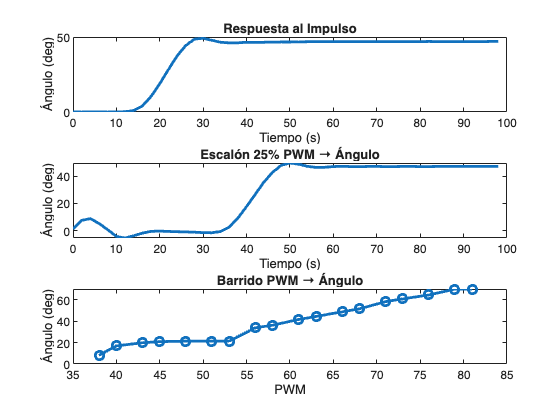


%% =============================================================
%  2) CREAR VECTOR DE TIEMPO (muestras cada 2 s)
% ==============================================================
Ts = 2; % s
t_imp = (0:Ts:(height(Impulso)-1)*Ts)';
t_esc = (0:Ts:(height(Escalon)-1)*Ts)';
t_bar = (0:Ts:(height(Barrido)-1)*Ts)';

%% =============================================================
%  3) GRAFICAR EXPERIMENTOS
% ==============================================================
figure;
subplot(3,1,1); plot(t_imp, Impulso.Angulo, 'LineWidth', 2);
title("Respuesta al Impulso"); xlabel("Tiempo (s)"); ylabel("Ángulo (deg)");

subplot(3,1,2); plot(t_esc, Escalon.Angulo, 'LineWidth', 2);
title("Escalón 25% PWM → Ángulo"); xlabel("Tiempo (s)"); ylabel("Ángulo (deg)");

subplot(3,1,3); plot(Barrido.PWM, Barrido.Angulo, 'o-','LineWidth', 2);
title("Barrido PWM → Ángulo"); xlabel("PWM"); ylabel("Ángulo (deg)");


%% =============================================================
%  4) LINEALIZACIÓN EN 25% PWM Y 47.37°
% ==============================================================
theta_inf = deg2rad(47.37);  
theta_max = deg2rad(49.92);  

Mp = (theta_max - theta_inf) / theta_inf;  
zeta = -log(Mp) / sqrt(pi^2 + log(Mp)^2);

Ts_est = 3.3; 
wn = 4/(zeta*Ts_est);

K = theta_inf * wn^2 / 0.25;  

disp("=== PARÁMETROS DEL MODELO MANUAL ===")

=== PARÁMETROS DEL MODELO MANUAL ===


K, zeta, wn

K = 10.4758

zeta = 0.6810

wn = 1.7798


%% =============================================================
%  5) MODELO LINEAL (LINEALIZADO)
% ==============================================================
num = K;
den = [1 2*zeta*wn wn^2];
G_manual = tf(num, den)


G_manual =
 
          10.48
  ---------------------
  s^2 + 2.424 s + 3.168
 
Continuous-time transfer function.


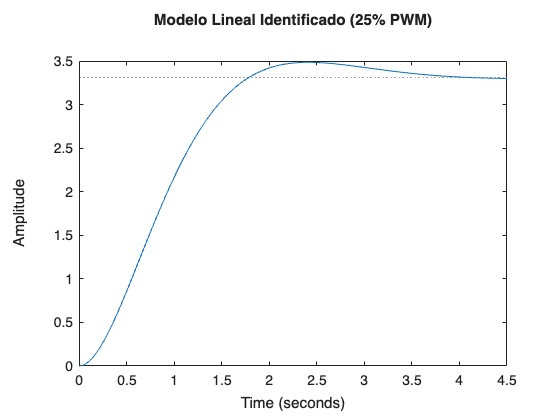


figure; step(G_manual)
title("Modelo Lineal Identificado (25% PWM)")


%% =============================================================
%  6) PID CONTINUO PARA ESTE MODELO
% ==============================================================
C_manual = pidtune(G_manual,'PID')


C_manual =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.664, Ki = 0.803, Kd = 0.137
 
Continuous-time PID controller in parallel form.


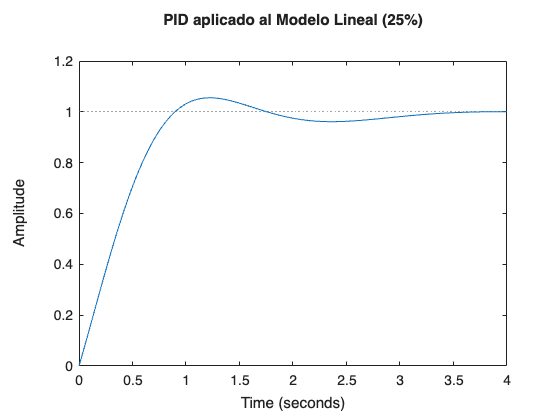


figure; step(feedback(C_manual*G_manual,1))
title("PID aplicado al Modelo Lineal (25%)")


%% =============================================================
%  7) MODELO NO LINEAL (DINÁMICA REAL)
% ==============================================================
M  = 0.034;
L  = 0.015;
g  = 9.81;
J  = 7.65e-6;
Bf = 1.967e-6;
Ku = 1.13e-2;

disp("Modelo NO lineal definido.");

Modelo NO lineal definido.


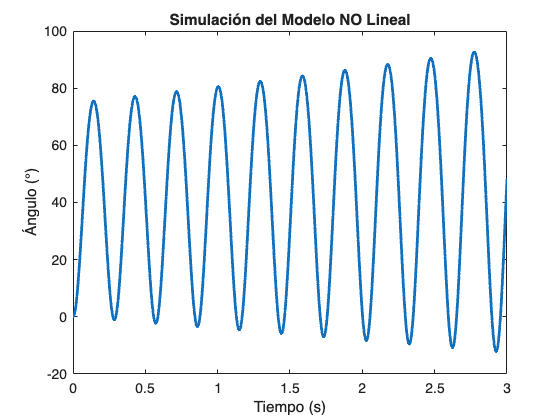


% --- FUNCIÓN DINÁMICA ---
dyn = @(t,x,u) [ ...
    x(2);  % theta_dot
    ( -M*g*L*sin(x(1)) - Bf*x(2) + Ku*u )/J ...
];

%% =============================================================
%  7B) SIMULACIÓN SENCILLA DEL MODELO NO LINEAL (SIN PID)
% ==============================================================
tspan = 0:0.001:3;   % tiempo de simulación
u_pwm = 0.25;        % entrada fija (25% PWM) — cámbiala si quieres

x = [0;0];           % estado inicial [theta; theta_dot]
theta_hist = zeros(size(tspan));

for k = 1:length(tspan)
    theta_hist(k) = x(1);

    dx = dyn(tspan(k), x, u_pwm);   % dinámica no lineal
    x = x + dx*0.001;               % integración Euler
end

figure;
plot(tspan, rad2deg(theta_hist),'LineWidth',2)
title("Simulación del Modelo NO Lineal")
xlabel("Tiempo (s)")
ylabel("Ángulo (°)")


%% =============================================================
%  8) IDENTIFICACIÓN CON TFEST (MODELO REAL)
% ==============================================================
Barrido18 = Caracterizacion(1:77, :);

data_ident = iddata( ...
      deg2rad(Barrido18.AnguloRelativo), ...
      Barrido18.PWM/100, ...
      Ts );

sys_ident = tfest(data_ident, 2,0)


sys_ident =
 
  From input "u1" to output "y1":
           0.001261
  --------------------------
  s^2 + 0.05421 s + 1.48e-11
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using TFEST on time domain data "data_ident".
Fit to estimation data: 90.13%                         
FPE: 0.001756, MSE: 0.001542                           
 
Model Properties


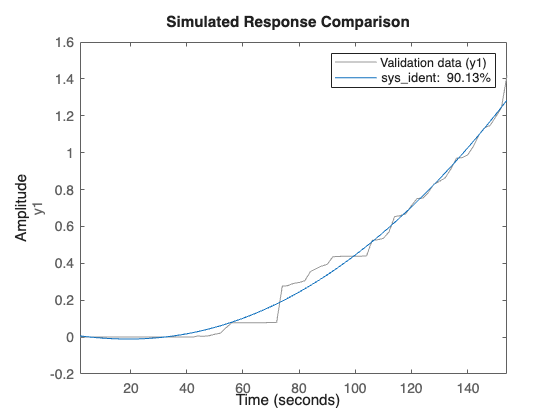


figure; compare(data_ident, sys_ident);


%% =============================================================
%  9) PID CONTINUO PARA sys_ident
% ==============================================================
C_ident = pidtune(sys_ident,'PID')


C_ident =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 5.39, Ki = 0.0825, Kd = 88
 
Continuous-time PID controller in parallel form.


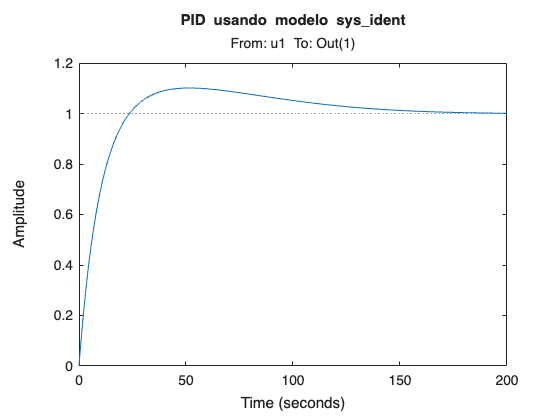


figure; step(feedback(C_ident*sys_ident,1))
title("PID usando modelo sys\_ident")


%% =============================================================
%  10) PID DISCRETO PARA ARDUINO (20 ms)
% ==============================================================
Ts_ardu = 0.02;

C_manual_d = c2d(C_manual, Ts_ardu,'tustin')


C_manual_d =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 0.664, Ki = 0.803, Kd = 0.137, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PID controller in parallel form.


C_ident_d  = c2d(C_ident , Ts_ardu,'tustin')


C_ident_d =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 5.39, Ki = 0.0825, Kd = 88, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PID controller in parallel form.



disp("=== PID DISCRETOS (PARA ARDUINO) ===")

=== PID DISCRETOS (PARA ARDUINO) ===


C_manual_d


C_manual_d =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 0.664, Ki = 0.803, Kd = 0.137, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PID controller in parallel form.


C_ident_d


C_ident_d =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 5.39, Ki = 0.0825, Kd = 88, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PID controller in parallel form.


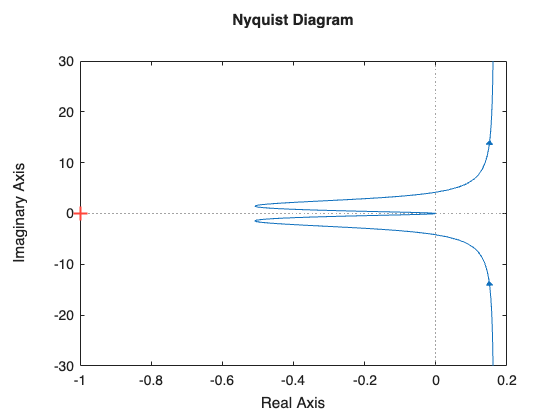


figure; nyquist(C_manual * G_manual)

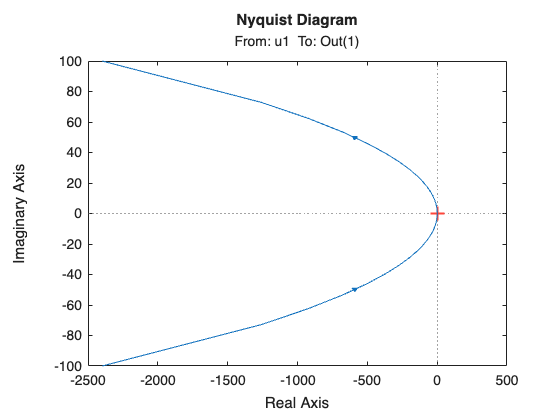

figure; nyquist(C_ident  * sys_ident)